img = imread("rice.png");

Averaging Filter

fAverage = fspecial("average", [3,3])

fAverage =     0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111


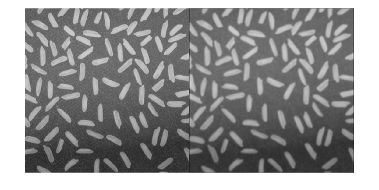

imgAveraged = imfilter(img, fAverage);
montage({img, imgAveraged})

Disk Filter

fDisk = fspecial("disk", 3)

fDisk =          0    0.0003    0.0110    0.0172    0.0110    0.0003         0
    0.0003    0.0245    0.0354    0.0354    0.0354    0.0245    0.0003
    0.0110    0.0354    0.0354    0.0354    0.0354    0.0354    0.0110
    0.0172    0.0354    0.0354    0.0354    0.0354    0.0354    0.0172
    0.0110    0.0354    0.0354    0.0354    0.0354    0.0354    0.0110
    0.0003    0.0245    0.0354    0.0354    0.0354    0.0245    0.0003
         0    0.0003    0.0110    0.0172    0.0110    0.0003         0


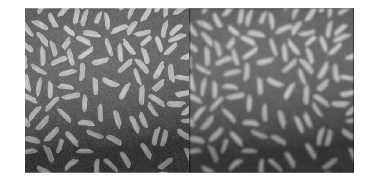

imgDisk = imfilter(img, fDisk);
montage({img, imgDisk})

Gaussian Filter

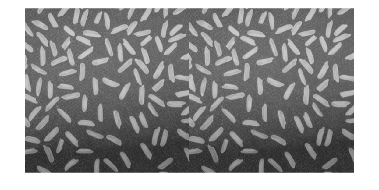

sigma = 0.3; % Standard deviation
filterSize = 3;
imgGaussFilt = imgaussfilt(img, sigma, FilterSize=filterSize);
montage({img, imgGaussFilt})

# Blurring Filter for General Image Manipulation

Motion

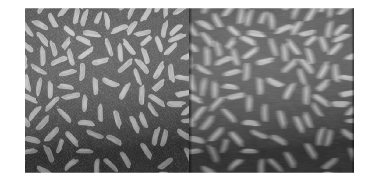

fMotion = fspecial("motion", 9, 0);
imgMotion = imfilter(img, fMotion);
montage({img, imgMotion})

## Edge Detection Filter

sobel

fSobel = fspecial("sobel")

fSobel =      1     2     1
     0     0     0
    -1    -2    -1


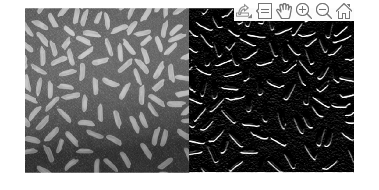

imgSobel = imfilter(img, fSobel);
montage({img, imgSobel})

Prewitt

fPrewitt = fspecial("prewitt")

fPrewitt =      1     1     1
     0     0     0
    -1    -1    -1


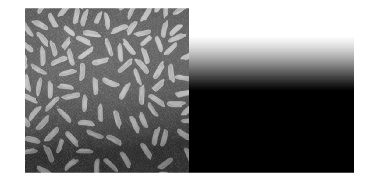

imgPrewitt = imfilter(img, fPrewitt);
montage({img, fPrewitt})

Laplacian

fLaplacian = fspecial("laplacian",0.2)

fLaplacian =     0.1667    0.6667    0.1667
    0.6667   -3.3333    0.6667
    0.1667    0.6667    0.1667


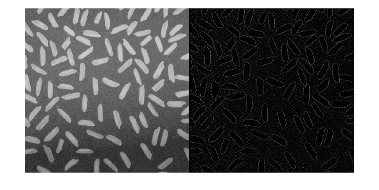

imgLaplacian = imfilter(img, fLaplacian);
montage({img, imgLaplacian})

## Blob Detection

Laplacian of Gaussian

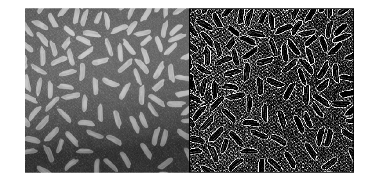

fLog = fspecial("log", [3, 3], 0.3); % filter size and standard deviation
imgLog = imfilter(img, fLog);
montage({img, imgLog})